# Filtro de Kalman Estendido

Em problemas do mundo real, o que a gente tem normalmente são problemas de engenharia (física) que são descritos por equações diferenciais não lineares. Sendo assim, a ideia é fazer uma apresentação do problema por meio de equações diferenciais não lineares.

## Equacionamento

As equações não lineares podem ser expressas como um conjunto não linear de primeira ordem conforme:


$$\dot{x} =f\left(x\right)+w$$


onde $x$ é o vetor de estados do sistema e $f\left(x\right)$é uma função não linear dos estados e $w$ o ruído de média zero do processo. A matriz do ruído do processo é dada por:


$$Q=E\left\lbrack {\mathrm{ww}}^T \right\rbrack$$


Finalmente a equação, necessária para aplicação do filtro de Kalman, é considerada também uma equação não linear:


$$y=h\left(x\right)+v$$


em que $v$ é o ruído de média zero de medida e tem matriz de ruído de medida dada por:


$$R=E\left\lbrack {\mathrm{vv}}^T \right\rbrack$$


Para sustemas discretos, as equações de medida pode ser reescritas como:


$$y_k =f\left(x_k \right)+v_k$$


e de forma equivalente, a gente consegue determinar, por meio de ruído discreto a matriz $R_k$.

Devido ao fato de as equações serem não lineares, tem-se que:


$$A = \left.\frac{\partial f(x)}{\partial x}\right|_{x = \hat{x}}
$$



$$C = \left.\frac{\partial h(x)}{\partial x}\right|_{x = \hat{x}}
$$


Perceba que ela é linearizada no entorno da melhor estimativa para os estados que a gente tem no momento (ou seja, em $x=\hat{x}$).

A matriz fundamental, necessária para utilização das equações de Riccati, pode ser aproximada por uma série de Taylor e é dada, no caso contínuo, por:


$$\Phi(t)=I+At+\frac{A^2t^2}{2!} +\frac{A^3t^3}{3!} + \dots$$


e no caso discreto por:


$$\Phi_k=I+AT_s+\frac{A^2T_s^2}{2!} +\frac{A^3T_s^3}{3!} + \dots$$


Normalmente a gente fará uma aproximação tomando apenas os dois primeiros termos dessa equação, ou seja:


$$\Phi_k \approx I + AT_s
$$


A gente já viu lá no Capítulo 5 que a aproximação doa matriz fundamental para determinação do ganho de Kalman é importante, uma vez que essa aproximação não degrada tanto assim a performane do filtro como um todo. Sendo assim só utilizaremos uma aproximação dessa matriz.

As equações de Riccati são as mesmas e aqui repetidas:


$$M_k = \Phi_{k}P_{k-1}\Phi_{k}^T + Q_k
$$



$$K_k = M_{k}C^T(CM_kC^T+R_k)^{-1}$$



$$P_k = (I-K_kC)M_k$$


em que $P_k$ representa a matriz de covariância de erros do estado estimados depois da atualização e a matriz $M_k$ representa a matriz de covariância de erros antes da atualização.

Como as matrizes $Q_k$ e $A$ são funções não lineares dos estados, os ganhos de Kalman não podem ser calculadas de forma *off-line*. Sendo assim, a matriz $Q_k$é dada de acordo com:


$$Q_k = \int_{0}^{T_s}\Phi(\tau)\textbf{Q}\Phi^{T}(\tau) d\tau$$


**Obs. 1:** Se a dinâmica do modelo linear é casada com o mundo real, a matriz de covariância $P_k$ não apenas calcula os ganhos de Kalman como também provê predições nos erros das estimativas dos estados.

**Obs. 2: **Para a dinâmica não linear o negócio é diferente, pois a matriz de covariância $P_k$ pode indicar uma perfomance excelente enquanto o filtro trabalha horrivelmente.

Para o cálculo das equações do filtro do Kalman, a gente determina o novo estado estimado por meio do antigo estado estimado projetado uma amostra a frente, ou seja:


$$\hat{x_k } =\overline{x} +K_k \left\lbrack y_k -h\left(\overline{x} \right)\right\rbrack$$


As estimativas das estimativas velhas são propagadas diretamente por meio da integração das equações não lineares a frente. No caso, fazendo uso da integração de Euler, tem-se que:


$$\hat{x}_{k} = \bar{x}_k + \hat{\dot{x}}_{k-1}T_s $$


e a derivada é obtida por:


$$\hat{\dot{x}}_{k-1} = f(\hat{x}_{k-1})$$


Vamos aplicar toda essa sopa de letrinhas por meio de um exemplo.

## Problema proposto

Objeto caindo (aos moldes do que foi feito com no Capítulo 4), só que nesse caso haverá um arrasto no processo como um todo. Olhando a dinâmica do objeto caindo, duas forças agem sobre o corpo apenas: o arrasto e a gravidade. Tendo o referencial positivo para cima, em termos de equacionamento, o que a gente tem é que:


$$\ddot{\text{ }x} =\mathrm{arrasto}-\mathrm{gravidade}$$



$$\ddot{\text{ }x} =\frac{Q_p g}{\beta \text{ }}-g$$


em que:


$$Q_p =\frac{\text{ }1}{2}\rho \text{ }{\dot{x} }^2$$


é a pressão dinâmica do sistema, o $\beta \text{ }$é o coeficiente balístico. Se ele for pequeno, significa dizer que o arrasto é significativo. Para valores mais altos, o arrasto tem pouca influência e para valores infinitos ter-se-ia o caso ideal (sem arrasto nenhum). Percebe-se pela equação da pressão dinâmica que ela depende da velocidade ($\dot{x\text{ }}$) e da densidade do ar ($\rho \text{ }$).

A densidade do ar varia com a altitude e é dada, para este problema, por:


$$\rho =0,0034e^{-\frac{x}{22000}}$$


Sendo assim, no intuito de "simplificar", vamos unir todas essas equações em apenas uma única equação, dada por:


$$\ddot{\text{ }x} =\frac{0,0034e^{-\frac{x}{22000}} {\dot{x} }^2 g}{2\beta \text{ }}-g$$


Vamos rodar essa simulação apenas para ver a dinâmica do sistema para diferentes valores de $\beta \ldotp \text{ }$Nesse caso, o objeto cairá de uma altura de 200.000 ft e terá uma velocidade inicial de 6.000 ft/s. A gravidade agindo no meio é 32,2 ft/s^2. Para fazer a dinâmica não linear do sistema, eu criei uma função de Runge-Kutta de 2º ordem e é dada por:

clear all; close all; clc;

% Condição inicial do meu problema.
X{1} = [200000; -6000];

% Possíveis valores testados de 'beta'
beta = [500, 1000, 2000, 9999999999999];

% Discretização do meu sistema.
H      = 0.001;
Ttotal = 30;
Ts     = H;

% Gravidade do meio (considerada constante).
g = 32.2;

% Vetores para dinâmica total do sistema.
dinT_x  = [];
dinT_xd = [];

% Roda o Runge-Kutta de 2º Ordem.
for j = 1:max(size(beta))
    for i = 1:(Ttotal/H)
        t(i) = H*i;
        
        % ==============================================================
        % As equações de Runge-Kuta de 2º ordem são simplificarmente, 
        % expressas por meio de:
        %
        %     c1 = f(x, t);
        %     c2 = f(x, t + h);
        %    
        %     x(k+1) = x(k) + (1/2)*(c1 + c2);
        % 
        % O que a gente tentará fazer aqui é reproduzir isso no inline.
        % ==============================================================
        
        % Pega os valores do vetor 'x'.
        % -----------------------------
        x(1) = X{i}(1,1);
        x(2) = X{i}(2,1);
        
        % Cálculo de c1.
        % --------------
        x_d = zeros(2,1);
        
        x_d(1) = x(2);
        x_d(2) = 0.0034*g*exp(-x(1)/22000)*(x(2)^2)/(2*beta(j)) - g;
        c1     = [x_d(1);
                  x_d(2)];
        
        % Cálculo de c2 -- Nosso caso não depende do tempo.
        % -------------------------------------------------
        x_d = zeros(2,1);
        
        x_d(1) = x(2);
        x_d(2) = 0.0034*g*exp(-x(1)/22000)*(x(2)^2)/(2*beta(j)) - g; 
        c2     = [x_d(1);
                  x_d(2)];
              
        % Dinâmica 'final'.
        % -----------------
        X{i+1} = X{i} + 0.5*H*(c1 + c2);
    end
    
    % Separa as variáveis.
    for i = 1:(Ttotal/H)
         x(i)      = X{i}(1,1);
         x_dot(i)  = X{i}(2,1);
    end
    
    % Salva as dinâmicas do sistema.
    dinT_x  = [dinT_x; x];
    dinT_xd = [dinT_xd; x_dot];
    
end

Realizarei o plot dos resultados obtidos no tocante ao exemplo proposto (apenas para identificarmos as questões de dinâmica e em outro momento inserirmos à dinâmica ruído gaussiano).

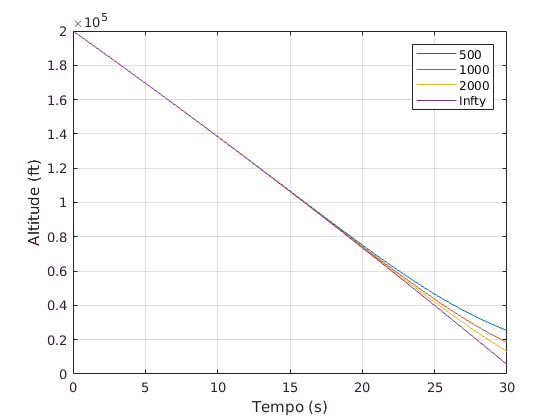

% Plota altitude.
for i = 1:4
    plot(t, dinT_x(i, 1:end)); hold on;
end
grid;
xlabel('Tempo (s)');
ylabel('Altitude (ft)');
legend('500', '1000', '2000', 'Infty');

Nesse sentido, percebe-se que menores valores de $\beta \text{ }$me dão um maior valor de arrasto (o deslocamenteo é sensivelmente menor para menores $\beta \text{ }$).

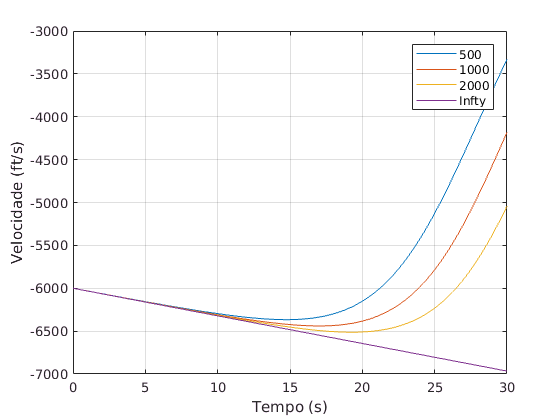

% Plota velocidade.
figure;
for i = 1:4
    plot(t, dinT_xd(i, 1:end)); hold on;
end
grid;
xlabel('Tempo (s)');
ylabel('Velocidade (ft/s)');
legend('500', '1000', '2000', 'Infty');

Verifica-se que quanto maior o valor de $\beta \text{ }$mais representa a situação ideal (sem arrasto). Nesse caso, os parâmetros de velocidade são bem amortecidos em casos de valores menores de $\beta \text{ }$.

Apresentado o problema, vamos agora para a abordagem do Filtro de Kalman.